Playing original signal...


Playing signal with echo...


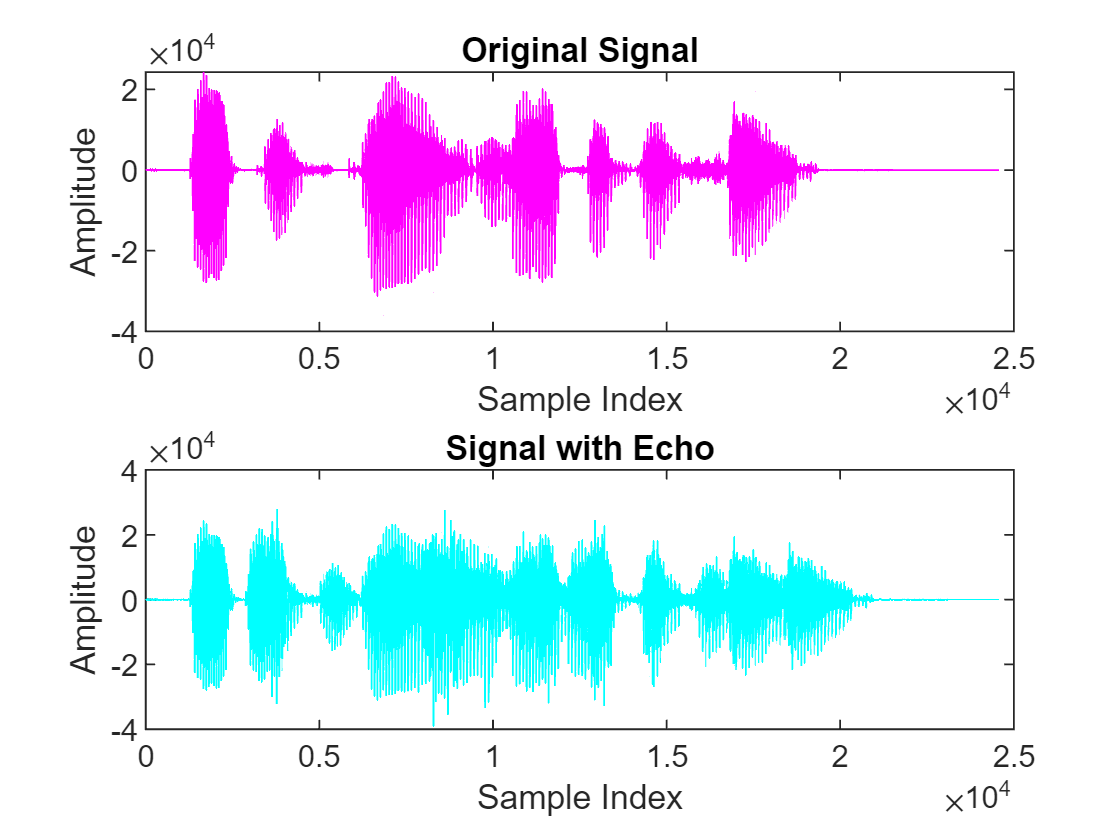

% Define the filter coefficients

r = 0.9;
P = 1600;
b = [1, zeros(1, P-1), r];

% Filter the signal to add the echo
y1 = filter(b, 1, x2);

% Play the original and the echoed signals for comparison
disp('Playing original signal...');
sound(x2, 8000);
pause(length(x2)/8000 + 2);

disp('Playing signal with echo...');
sound(y1, 8000);

% Plot the original and echoed signals for visual inspection
figure;
subplot(2,1,1);
plot(x2, 'm');
title('Original Signal');
xlabel('Sample Index');
ylabel('Amplitude');

subplot(2,1,2);
plot(y1, 'c');
title('Signal with Echo');
xlabel('Sample Index');
ylabel('Amplitude');